# Cálculo de $\pi$

Monte Carlo methods, or Monte Carlo experiments, are a broad class of computational algorithms that rely on repeated **random sampling** to obtain numerical results.

[https://en.wikipedia.org/wiki/Monte_Carlo_method#Integration](https://en.wikipedia.org/wiki/Monte_Carlo_method#Integration)

## Area method

This method enables you to estimate areas (**definite integrals**) by generating a uniform sample of points and counting how many fall into a planar region.

If you generate a 2-D point (an ordered pair) uniformly at random within the unit square, then the probability that the point is inside the quarter circle is equal to the ratio of the area of the quarter circle divided by the area of the unit square. That is, P(point inside circle) = Area(quarter circle) / Area(unit square) = $\frac{\pi }{4}$

It is easy to use a Monte Carlo simulation to estimate the probability P:

- generate *n* random points uniformally distributed inside the unit square, and

- count the proportion that fall in the quarter circle

Genera 10000 puntos aleatorios

n = 10000

n = 10000

x = rand(n,1);
y = rand(n,1);
r2 = x.^2+y.^2;

Encuentra los puntos que se encuentran dentro del área de interés (distancia al origen menor a 1) y fuera de ella

inside = r2 <= 1; %Exito
outside = r2 > 1; %Fracaso

Grafica los puntos que caen adentro en azul y los que caen afuera en rojo

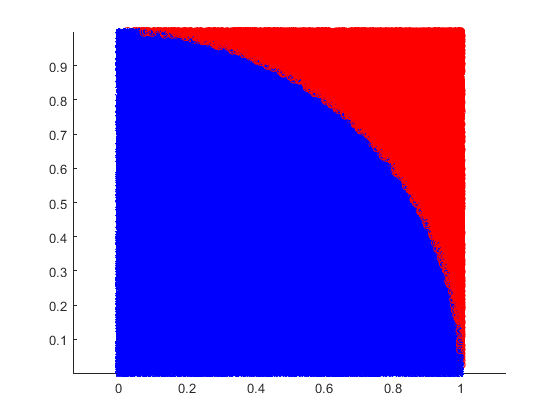

hold on;
plot(x(inside), y(inside), "bx", x(outside),y(outside), "ro")
axis equal;
hold off;

Encuentra la proporción de puntos que están adentro (p) y de puntos que están afuera (q)

% la proporción se obtiene con el número de casos sobre el número total
p = mean(inside)

p = 0.7857

q = mean(outside)

q = 0.2143

Encuentra la desviación estándar (proceso de Bernoulli)

%La desviación estandar es la raiz de la varianza (varianza de la Bernoulli Var=p(1-p)) 
desv= std(inside)

desv = 0.4104

Calcula el intervalo de confianza (95%) para una proporción

%el intervalo de confianza está dado como []
z=1.95996

z = 1.9600

fprintf('%7.4f +/- %6.4f\n', p*4, desv*z)

 3.1428 +/- 0.8043


Repite el mismo experimento 100 veces, calcula la varianza, el error estándar y el intervalo de confianza.

M=100;
v=zeros(1,M);
for c=1:M;
    x= rand (n,1); 
    y =rand (n,1);
    r2 = x.^2+y.^2;
    dentro = r2 <= 1;
    v(c)=mean(dentro)*4;
end
media=mean(v);    
desV = std(v);
error = desV/sqrt(M);
fprintf('%7.4f +/- %6.4f\n', media, z*error)

 3.1418 +/- 0.0030


pi

ans = 3.1416

## Fórmula de Leibniz 

$\frac{\pi }{4}$=$1-\frac{1}{3}$$+\frac{1}{5}-\frac{1}{7}+\frac{1}{9}$-$\cdots$

Calcula el valor de $\pi$ usando la fórmula anterior. Detén el cálculo cuando la diferencia relativa entre el valor actual calculado y el anterior calculado sea menor a 0.0000001 o se hayan realizado 200 mil iteraciones.

% error de truncamiento
s=1;
difR=0;
leib=0;
while s < 200e3 | difR == 1e-7
    act=leib + (-1)^(s+1)/(2*s-1);
    difR=act-leib;
    leib= act;
    s=s+1;
end
s

s = 200000

difR

difR = 2.5000e-06

leib

leib = 0.7854

pi/4

ans = 0.7854